# Problem 1

Consider a pillar made of two block pieces with the dimensions shown in the Figure and vertical lengths $h_{1}=2$, $h_{2}=4$, in a certain unit system. Only for academic purposes we can consider that the Young modulus of the material is $E = 2$and the specific weight is $w = 0.01$. 

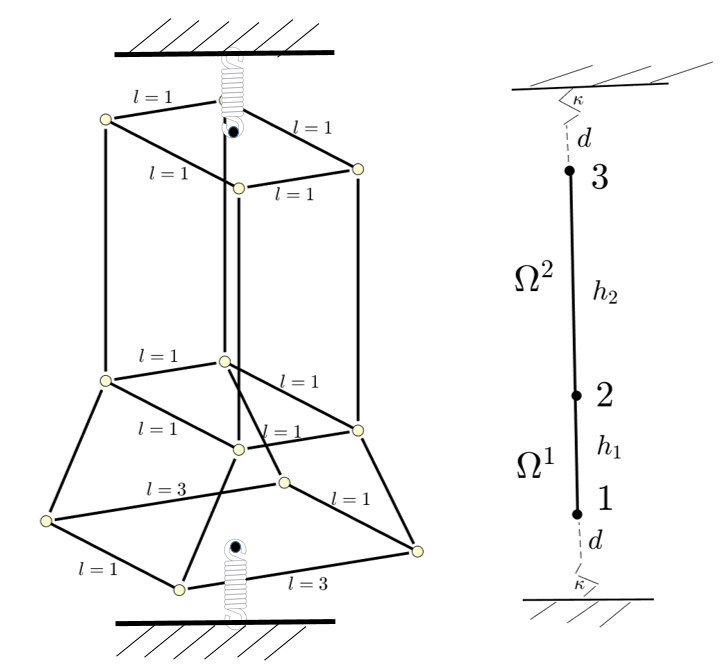

We want to study the elastic deformation of the pillar through the Finite Element Method with **two linear elements** as symbolically are shown in the figure.  Also, as it is seen, we assume that  the top and the bottom of the column are both initially placed at a  distance $d = 1$of a two anti-vibration springs system of recovering constant $\kappa = 1$. Then we attach the pillar to the two anti-vibration spring system. We  want to study the deformation of the pillar caused by the weight and the spring recovering forces. In order to avoid unnecessary calculations you can use the formulas of $K$ and $F$ when they depend linearly on x. You have to answer the following questions:

clearvars
close all
format short e
%
% Data
%
L1 = 3.0; L2 = 1.0; 
w = 0.01; d = 1.0; ks = 1.0; 

% # 6
h1 = 2.0; h2 = 4.0; E = 2.0;

## (a) [2 points]

The entry $K_{22}$ of the stiff matrix of the global assembled system is 

$\bullet$Leave it empty (no penalty)

$\lozenge$2.5000e+00

$\bullet$2.1984e+00

$\bullet$3.9973e-01

$\bullet$3.7518e+00

$\bullet$4.1585e+00

**Hint 1**: The value of $K_{23}$ is $K_{23} =$ -5.0000e-01

% Geometry
A1 = L1*L2;
A2 = L2*L2;

%Element 1
alpha = -(A1-A2)/h1;
beta = A1;                     %A(x) = alpha * x + beta
x1_elem_1 = 0; x2_elem_1 = h1; %Positions element one's nodes
K1 = 0.5*alpha*E*(x1_elem_1+x2_elem_1)*[1,-1;-1,1]/h1 + ...
    beta*E*[1,-1;-1,1]/h1;

%Element 2
K2 = E*A2*[1,-1;-1,1]/h2;

%Assemble matrices
K = zeros(3);
K(1:2,1:2) = K1;
K(2:3,2:3) = K(2:3,2:3)+K2

K =    2.0000e+00  -2.0000e+00            0
  -2.0000e+00   2.5000e+00  -5.0000e-01
            0  -5.0000e-01   5.0000e-01


fprintf(['Part A\n',...
    'The entry K(2,2) of the stiff matrix of the global system is K(2,2) = %.4e\n',...
    'Hint 1. The value of K(2,3) is K(2,3) = %.4e\n'],K(2,2),K(2,3))

Part A
The entry K(2,2) of the stiff matrix of the global system is K(2,2) = 2.5000e+00
Hint 1. The value of K(2,3) is K(2,3) = -5.0000e-01


### Solution of part (a)

$K_{2 2} =$ 2.5000e+00 $\triangleright$

## (b) [3 points]

The second component of the global assembled force $F_{2}$ is

$\bullet$Leave it empty (no penalty)

$\bullet$-7.1408e-02

$\lozenge$-3.6667e-02

$\bullet$-5.6780e-02

$\bullet$-3.7394e-02

$\bullet$-2.1045e-02

**Hint 2: **The value of $F_{3}$ is  $F_{3} =$ -2.0000e-02

% Element 1ç
F1 = -alpha*w*h1*[2*x1_elem_1+x2_elem_1; x1_elem_1+2*x2_elem_1]/6 + ...
    -beta*w*h1*[1;1]/2;
% Element 2
F2 = -w*A2*h2*[1;1]/2.0;

% Assemble forces
F = zeros(3,1);
F(1:2) = F1;
F(2:3) = F(2:3) + F2

F =   -2.3333e-02
  -3.6667e-02
  -2.0000e-02


fprintf(['Part B\n',...
    'The value of F(2) is, F(2) = %.4e\n',...
    'Hint 2. The value of F(3) is, F(3) = %.4e\n'],F(2),F(3))

Part B
The value of F(2) is, F(2) = -3.6667e-02
Hint 2. The value of F(3) is, F(3) = -2.0000e-02


### **Solution of part (b)**

$F_{2} =$ -3.6667e-02 $\triangleright$

## (c) [5 points]

Using that, in node 1, the secondary variable is $Q_{1} = -\kappa (d + U_{1})$. Then the displacement $U_{2}$ of the global node $2$ is ( you can use Hint 3) 

$\bullet$Leave it empty (no penalty)

$\lozenge$-3.9222e-01

$\bullet$-3.3523e-01

$\bullet$-4.3748e-01

$\bullet$-6.1825e-01

$\bullet$-4.3911e-02

**Hint 3:** The value of $U_{1}$ is  $U_{1} =$ -6.0259e-01

Km = K+[ks,0,0;0,0,0;0,0,ks];
Qm = F+d*ks*[-1;0;1];
U = Km\Qm

U =   -6.0259e-01
  -3.9222e-01
   5.2259e-01


fprintf(['Part C\n',...
    'Displacement U(2) of the global node 2, U(2) = %.4e\n',...
    'Hint 3. The value of U(1) is U(1) = %.4e\n'],U(2),U(1))

Part C
Displacement U(2) of the global node 2, U(2) = -3.9222e-01
Hint 3. The value of U(1) is U(1) = -6.0259e-01


### Solution of part (c)

$U_{2} =$ -3.9222e-01 $\triangleright$

[Km Qm]

ans =    3.0000e+00  -2.0000e+00            0  -1.0233e+00
  -2.0000e+00   2.5000e+00  -5.0000e-01  -3.6667e-02
            0  -5.0000e-01   1.5000e+00   9.8000e-01
